# Cvičení 7 - B2M31AEDA

## Nahrání dat

**Důležité! **V dnešním cvičení naleznete opět na Moodle ke stažení dva data sety, data.csv a large_dataset.csv. Zopakujete si princip vyšetření potřebné velikosti vzorku, který jste se naučili minule.

## ČTĚTE POZORNĚ ZADÁNÍ!!! 😊

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week07' '\sem'])))
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
T = readtable('large_dataset.csv','ReadVariableNames',true);
data = struct( ...
    'Subject', repelem(struct( ...
        'ID', NaN, ...
        'AP', NaN, ...
        'Gender', NaN, ...
        'Medication', NaN, ...
        'Motor', NaN, ...
        'Dysarthria', NaN, ...
        'RST', NaN ...
    ), height(T)), ...
    'Length', height(T));

for k = 1:data.Length
    data.Subject(k).ID = char(T.subject(k));
    data.Subject(k).AP = ismember('HD_AP', T.group(k));
    data.Subject(k).Gender = char(T.gender(k));
    data.Subject(k).Medication = T.medication(k);
    data.Subject(k).Motor = T.motor(k);
    data.Subject(k).Dysarthria = T.dysarthria(k);
    data.Subject(k).RST = T.RST(k);
end

## 1. Estimace potřebné velikosti vzorku

Zde budete, podobně jako v minulém cvičení, zjišťovat minimální velikost vzorku potřebnou pro váš test. V tomto cvičení budete pracovat s dvoucestnou ANOVA (2-way ANOVA).

**Otázky:**

- Tentokrát nemáme k dispozici data u přechozích studií pro odhad populačních statistik, proto cílovou sílu efektu zvolíme jako „velkou“. Čemu numericky odpovídá „velká“ konzultujte s manuálem programu GPower. Sílu efektu budeme chtít dosáhnout pro hladiny α = 0.05 a β = 0.2.

- Zaznamenejte jaký dataset jste se rozhodli použít a jaké to bude mít následky!

Za předpokladu, že by ani jeden dataset svojí velikostí nedostačoval pro požadovanou velikost vzorku, proveďte všechny další analýzy stejně, ale k této části **do Moodlu slovně napište, jak to ovlivní interpretaci vašich výsledků s ohledem na chybu II. typu.**

#### Vaše odpovědi a výsledky:

- Pro "velkou" sílu efektu, tj. dle programu G*Power pro sílu efektu 0.4 a hladiny $\alpha =0\ldotp 05$ a $\beta =0\ldotp 2$ je minimální velikost vzorku 52. Pro zmenšení pravděpodobnosti chyby II. typu tedy využijeme většího datasetu o velikosti 38. Vzhledem k tomu, že ani pro větší dataset nedosahuje požadované síly testu, budeme nadále brát v potaz zvýšenou pravděpodobnost chyby II. typu, která se dá odhadnout pomocí post-analýzy v G*Power: Pro velikost vzorku 38 vychází výsledná síla testu $1-\beta \approx 0\ldotp 67$, což implikuje pravděpodobnost chyby II. typu $\beta =0\ldotp 33$.

## 2. Analýza 1

V této úloze je vizualizace dat zcela dobrovolná a nebude hodnocena, nicméně ji samozřejmě zcela doporučujeme zejména k lepšímu porozumění pozorovaných efektů.

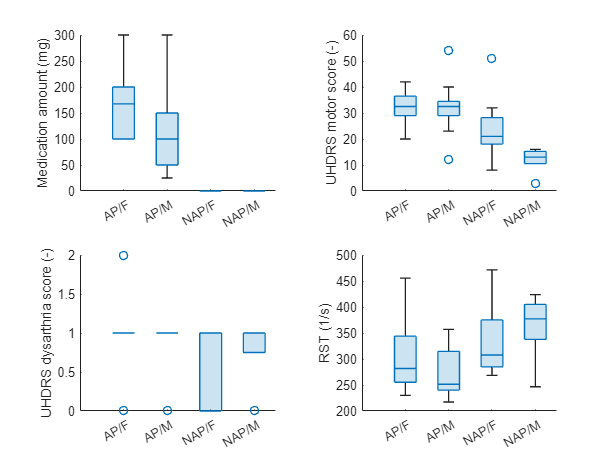

figure(1)
tiles = tiledlayout(2,2);
parameter = ["Medication", "Motor", "Dysarthria", "RST"];
label = ["Medication amount (mg)", "UHDRS motor score (-)", "UHDRS dysarthria score (-)", "RST (1/s)"];
for i = 1:4
    AP_F = [data.Subject([data.Subject.AP].*[data.Subject.Gender] == 'F').(parameter(i))]';
    AP_M = [data.Subject([data.Subject.AP].*[data.Subject.Gender] == 'M').(parameter(i))]';
    NAP_F = [data.Subject(~[data.Subject.AP].*[data.Subject.Gender] == 'F').(parameter(i))]';
    NAP_M = [data.Subject(~[data.Subject.AP].*[data.Subject.Gender] == 'M').(parameter(i))]';
    xgroupdata = [1*ones(length(AP_F), 1); 2*ones(length(AP_M), 1); 3*ones(length(NAP_F), 1); 4*ones(length(NAP_M), 1)];
    ydata = [AP_F; AP_M; NAP_F; NAP_M];
    nexttile
    boxchart(xgroupdata, ydata)
    xticklabels(["", "AP/F", "AP/M", "NAP/F", "NAP/M"])
    ylabel(label(i))
end

**Analýza normality a homoskedasticity dat**

Rozdělení skupin:

- *AP: *Skupina subjektů vystavená léčbě pomocí antipsychotik

- *NAP: *Skupina subjektů nevystavená léčbě pomocí antipsychotik

- *F: *Skupina subjektů ženského pohlaví

- *M: *Skupina subjektů mužského pohlaví

- *AP_F: *Skupina subjektů ženského pohlaví vystavená léčbě pomocí antipsychotik

- *AP_M: *Skupina subjektů mužského pohlaví vystavená léčbě pomocí antipsychotik

- *NAP_F: *Skupina subjektů ženského pohlaví nevystavená léčbě pomocí antipsychotik

- *NAP_M: *Skupina subjektů mužského pohlaví nevystavená léčbě pomocí antipsychotik

Normalita dat:

- Nulová hypotéza: Vstupní data jsou normálně rozdělena.

- Alternativní hypotéza: Vstupní data nejsou normálně rozdělena.

- Hladina statistické významnosti: $\alpha =0\ldotp 05$.

alpha = 0.05;
AP = [data.Subject([data.Subject.AP]).RST]';
NAP = [data.Subject(~[data.Subject.AP]).RST]';
F = [data.Subject([data.Subject.Gender] == 'F').RST]';
M = [data.Subject([data.Subject.Gender] == 'M').RST]';
AP_F = [data.Subject([data.Subject.AP].*[data.Subject.Gender] == 'F').RST]';
AP_M = [data.Subject([data.Subject.AP].*[data.Subject.Gender] == 'M').RST]';
NAP_F = [data.Subject(~[data.Subject.AP].*[data.Subject.Gender] == 'F').RST]';
NAP_M = [data.Subject(~[data.Subject.AP].*[data.Subject.Gender] == 'M').RST]';

for sample = ["AP", "NAP", "F", "M", "AP_F", "AP_M", "NAP_F", "NAP_M"]
    [H, pValue, SWstatistic] = swtest(eval(sample), alpha);

    if pValue < 0.001
        pReport = "p < 0.001";
    elseif pValue < 0.01
        pReport = sprintf('p = %.3f', pValue);
    else
        pReport = sprintf('p = %.2f', pValue);
    end

    if H == 0
        fprintf(['\tShapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption\n' ...
            'regarding the population distribution of a random sample %s (M = %.2f, SD = %.2f) at significance level α = %.2f,\n' ...
            'W(%d) = %.4f, %s.\n\n'], ...
            sample, mean(eval(sample)), std(eval(sample)), alpha, length(eval(sample))-1, SWstatistic, pReport)
    else
        fprintf(['\tShapiro-Wilk test rejects the null hypothesis of composite normality regarding the population\n' ...
            'distribution of a random sample %s (M = %.2f, SD = %.2f) at significance level α = %.2f,\n' ...
            'W(%d) = %.4f, %s.\n\n'], ...
            sample, mean(eval(sample)), std(eval(sample)), alpha, length(eval(sample))-1, SWstatistic, pReport)
    end
end

	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample AP (M = 285.23, SD = 59.21) at significance level α = 0.05,
W(20) = 0.8755, p = 0.01.



	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample NAP (M = 340.34, SD = 63.58) at significance level α = 0.05,
W(16) = 0.9535, p = 0.51.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample F (M = 320.93, SD = 66.21) at significance level α = 0.05,
W(19) = 0.9141, p = 0.08.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample M (M = 297.62, SD = 66.37) at significance level α = 0.05,
W(17) = 0.8981, p = 0.05.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample AP_F (M = 305.94, SD = 73.67) at significance level α = 0.05,
W(7) = 0.8848, p = 0.18.

	Shapiro-Wil

Homoskedasticita:

- Nulová hypotéza: Variance vstupních dat vykazuje homogenitu.

- Alternativní hypotéza: Variance vstupních dat nevykazuje homogenitu.

- Hladina statistické významnosti: $\alpha =0\ldotp 05$.

V případě skupin *AP/NAP *a *F/M *budeme předpoklad homoskedasticity považovat za splněný, neboť skupiny jsou porovnatelné velikosti (poměr největší/nejmenší velikosti skupin není větší než 1.5). Pro skupinu *AP_F/AP_M/NAP_F/NAP_M *provedeme Bartlettův test.

alpha = 0.05;
label = cell(data.Length, 1);
for i=1:data.Length
    if data.Subject(i).AP && data.Subject(i).Gender == 'F'
        label{i} = 'AP_F';
    elseif data.Subject(i).AP && data.Subject(i).Gender == 'M'
        label{i} = 'AP_M';
    elseif ~data.Subject(i).AP && data.Subject(i).Gender == 'F'
        label{i} = 'NAP_F';
    else
        label{i} = 'NAP_M';
    end
end

[pValue, stats] = vartestn(T.RST, label, 'TestType', "Bartlett", 'Display', 'off');
fprintf("Bartlett's test results for groups AP_F/AP_M/NAP_F/NAP_M: B(%d) = %.4f, p = %.2f.\n" + ...
    "Null hypothesis is confirmed at a significance level α = %.2f.\n" + ...
    "Sampled data shows equality of variances.", ...
 stats.df, stats.chisqstat, pValue, alpha);

Bartlett's test results for groups AP_F/AP_M/NAP_F/NAP_M: B(3) = 1.9391, p = 0.59.
Null hypothesis is confirmed at a significance level α = 0.05.
Sampled data shows equality of variances.

**Na následující dvě otázky odpovězte pomocí jediného testu.**

- *Mají pacienti s HN beroucí antipsychotickou medikaci statisticky významně změněnou rychlost řeči oproti pacientům, kteří antipsychotika neberou?*

- *Lze pozorovat statisticky významné změny v rychlosti řeči způsobené antipsychotickými léky specificky (pouze) pro jedno z pohlaví?*

[pValue, table, stats, ~] = anovan( ...
    T.RST, {T.group, T.gender}, ...
    'varnames', {'medication', 'sex'}, ...
    'model', 'interaction', ...
    'Display', 'off');
pReport = cell(1,3);
for i = 1:3
    if pValue(i) < 0.001
        pReport{i} = "p < 0.001";
    elseif pValue(i) < 0.01
        pReport{i} = sprintf('p = %.3f', pValue(i));
    else
        pReport{i} = sprintf('p = %.2f', pValue(i));
    end
end

fprintf("Multiple factor ANOVA test based on RST parameter, for variables of medication and sex was performed.\n" + ...
    "The results indicated:\n" + ...
    "A statistically significant main effect with α = 0.05 for variable of medication,\n" + ...
    "\tF(%d,%d) = %.3f, %s.\n" + ...
    "No statistically significant main effect with α = 0.05 for second variable of sex was found,\n" + ...
    "\tF(%d,%d) = %.3f, %s.\n" + ...
    "No statistically significant significant interaction between variables with α = 0.05 was found,\n" + ...
    "\tF(%d,%d) = %.3f, %s.", ...
    1, stats.dfe, table{2,6}, pReport{1}, 1, stats.dfe, table{3,6}, pReport{2}, 1, stats.dfe, table{4,6}, pReport{3});

Multiple factor ANOVA test based on RST parameter, for variables of medication and sex was performed.
The results indicated:
A statistically significant main effect with α = 0.05 for variable of medication,
	F(1,34) = 7.437, p = 0.01.
No statistically significant main effect with α = 0.05 for second variable of sex was found,
	F(1,34) = 0.001, p = 0.97.
No statistically significant significant interaction between variables with α = 0.05 was found,
	F(1,34) = 2.393, p = 0.13.

**Následující otázku musíte řešit testem zvlášť od prvních dvou.**

         3. *Pokud bychom brali hodnocení stavu motoriky na škále UHDRS jako nezávislý kovariát (spojitý faktor), jaký bude mít vliv na výsledky z první otázky?*

[pValue, table, stats, ~] = anovan( ...
    T.RST, {T.group, T.gender, T.motor}, ...
    'varnames', {'medication', 'sex', 'UHDRS'}, ...
    'continuous', 3, ...
    'model', 'interaction', ...
    'Display', 'off');

pReport = cell(1,6);
for i = 1:6
    if pValue(i) <= 0.001
        pReport{i} = "p < 0.001";
    elseif pValue(i) <= 0.01 && pValue(i) > 0.001
        pReport{i} = sprintf('p = %.3f', pValue(i));
    else
        pReport{i} = sprintf('p = %.2f', pValue(i));
    end
end

fprintf("Multiple factor ANOVA test based on RST parameter, for variables of medication, sex and\n" + ...
    "continuous variable of UHDRS was performed. With α = 0.05, the results indicated:\n" + ...
    "No statistically significant main effect for any of the variables:\n" + ...
    "\tmedication, F(%d,%d) = %.3f, %s,\n" + ...
    "\tsex, F(%d,%d) = %.3f, %s,\n" + ...
    "\tUPDRS, F(%d,%d) = %.3f, %s.\n" + ...
    "Additionally, no significant interaction between varibales was indicated:\n" + ...
    "\tmedication-sex, F(%d,%d) = %.3f, %s,\n" + ...
    "\tmedication-UHDRS, F(%d,%d) = %.3f, %s,\n" + ...
    "\tsex-UHDRS, F(%d,%d) = %.3f, %s.",...
    1, stats.dfe, table{2,6}, pReport{1}, 1, stats.dfe, table{3,6}, pReport{2}, 1, stats.dfe, table{4,6}, pReport{3},...
    1, stats.dfe, table{5,6}, pReport{4},1, stats.dfe, table{6,6}, pReport{5},1, stats.dfe, table{7,6}, pReport{6});

Multiple factor ANOVA test based on RST parameter, for variables of medication, sex and
continuous variable of UHDRS was performed. With α = 0.05, the results indicated:
No statistically significant main effect for any of the variables:
	medication, F(1,29) = 0.548, p = 0.47,
	sex, F(1,29) = 0.272, p = 0.61,
	UPDRS, F(1,29) = 0.972, p = 0.33.
Additionally, no significant interaction between varibales was indicated:
	medication-sex, F(1,29) = 0.725, p = 0.40,
	medication-UHDRS, F(1,29) = 0.008, p = 0.93,
	sex-UHDRS, F(1,29) = 0.102, p = 0.75.

U otázek v této i následující části si dejte záležet na korektním provedení testu a intepretaci výsledků.

- Testování normality/homoskedasticity vám dá informaci o tom, jak budou výsledky ovlivněné chybou I. typu, pokud vstupní data nebudou normální, protože zde není možnost použít neparametrickou metodu pro více-faktorové testování.

- Výsledky, jako vždy, korektně reportujte.

#### **Interpretace:**

Vzhledem k požadavkům na normalitu a homoskedasticitu dat byl použit test MANOVA pro získání informace o statistický významných efektech mezi skupinami a jejich vzájemných interakcích. Jediný porušený požadavek je v případě RST pro skupinu subjektů vystavených léčbě antipsychotik (skupina *AP*), a přisuzujeme tak vyšší pravděpodobnost chyby I. typu pro tuto skupinu.

Test ukázal významný efekt pouze pro skupiny *AP/NAP*, tj. pro proměnnou medikace pomocí antipsychotik, které pomáhají snížit RST, a tedy indikovat zlepšení pacientova stavu. Proměnná pohlaví neprokázala v rámci testu významný efekt, stejně jako interakce mezi proměnnými.

- Ano, mezi subjekty trpícími Huntingtonovou nemocí, které podstoupily a nepodstoupily léčbu pomocí antipsychotik, existuje statisticky významný efekt.

- Ne. Jelikož se nepodařilo prokázat existenci interakce mezi proměnnými, nelze pozorovat statisticky významné změny v rychlosti řeči způsobené antipsychotickými léky specificky  (pouze) pro jedno z pohlaví.

- Nezávislý kovariát UHDRS skóre změnil výsledky původního testu v tom smyslu, že proměnná podstoupení léčby antipsychotiky ztratila na efektu.

## 3. Analýza 2

Rozdělme si pacienty na ty s postiženou řečí a ty bez postižené řeči – to můžeme provést na základě klinického hodnocení řeči skrytého pod položkou dysarthria, kde hodnota 0 znamená nepostiženou řeč, všechny ostatní hodnoty pak řeč (různě) postiženou.

- *Mají pacienti s poruchou řeči ve srovnání s pacienty bez poruchy řeči významně zhoršené hodnoty motorického hodnocení UHDRS, pokud budeme brát v potaz i vliv toho, jestli berou antipsychotika, nebo ne?*

affected.all = find([data.Subject.Dysarthria] ~= 0 & ~isnan([data.Subject.Dysarthria]));
affected.men = find([data.Subject.Dysarthria] ~= 0 & ~isnan([data.Subject.Dysarthria]) & [data.Subject.Gender] == 'M');
affected.women = find([data.Subject.Dysarthria] ~= 0 & ~isnan([data.Subject.Dysarthria]) & [data.Subject.Gender] == 'F');
unaffected.all = find([data.Subject.Dysarthria] == 0);
unaffected.men = find([data.Subject.Dysarthria] == 0 & [data.Subject.Gender] == 'M');
unaffected.women = find([data.Subject.Dysarthria] == 0 & [data.Subject.Gender] == 'F');

condition(affected.all) = {"Affected"};
condition(unaffected.all) = {"Unaffected"};
condition = [condition{:}];
gender = [data.Subject(sort([affected.all, unaffected.all])).Gender];
UHDRS = [data.Subject(sort([affected.all, unaffected.all])).Motor];

[p_dyst, table_dyst, stats_dyst, terms_dyst] = anovan( ...
    UHDRS, {condition, gender}, ...
    'varnames', {'condition', 'gender'}, ...
    'model', 'interaction', ...
    'Display', 'off');

pReport = cell(1,3);
for i = 1:3
    if p_dyst(i) <= 0.001
        pReport{i} = "p < 0.001";
    elseif p_dyst(i) <= 0.01 && p_dyst(i) > 0.001
        pReport{i} = sprintf('p = %.3f', p_dyst(i));
    else
        pReport{i} = sprintf('p = %.2f', p_dyst(i));
    end
end

fprintf("Multiple factor ANOVA test was performed based on UHDRS scores, for the level of statistical\n" + ...
    "significance α = 0.05 and variables of subject's dysarthric speech condition and sex, i.e.\n" + ...
    "\tunaffected males (M = %.3f, SD = %.3f),\n" + ...
    "\taffected males (M = %.3f, SD = %.3f),\n" + ...
    "\tunaffected females (M = %.3f, SD = %.3f),\n" + ...
    "\taffected females (M = %.3f, SD = %.3f).\n" + ...
    "The results indicated statistically significant a main effect for variables:\n" + ...
    "\tdysarthria, F(%d,%d) = %.3f, %s.\n" + ...
    "No main effect was found for variables:\n" + ...
    "\tsex, F(%d,%d) = %.3f, %s.\n" + ...
    "No significant interaction between variables was found:\n" + ...
    "\tF(%d,%d) = %.3f, %s.",...
    mean([data.Subject(unaffected.men).Motor]), std([data.Subject(unaffected.men).Motor]), ...
    mean([data.Subject(affected.men).Motor]), std([data.Subject(affected.men).Motor]), ...
    mean([data.Subject(unaffected.women).Motor]), std([data.Subject(unaffected.women).Motor]), ...
    mean([data.Subject(affected.women).Motor]), std([data.Subject(affected.women).Motor]), ...
    1, stats_dyst.dfe, table_dyst{2,6}, pReport{1}, 1, stats_dyst.dfe, table_dyst{3,6}, pReport{2}, 1, stats_dyst.dfe, table_dyst{4,6}, pReport{3});

Multiple factor ANOVA test was performed based on UHDRS scores, for the level of statistical
significance α = 0.05 and variables of subject's dysarthric speech condition and sex, i.e.
	unaffected males (M = 19.000, SD = 22.627),
	affected males (M = 27.267, SD = 11.937),
	unaffected females (M = 16.000, SD = 5.550),
	affected females (M = 32.154, SD = 8.325).
The results indicated statistically significant a main effect for variables:
	dysarthria, F(1,32) = 6.743, p = 0.01.
No main effect was found for variables:
	sex, F(1,32) = 0.040, p = 0.84.
No significant interaction between variables was found:
	F(1,32) = 0.703, p = 0.41.

#### **Interpretace:**

Test MANOVA nám pomohl zjistit, že statisticky významný efekt existuje pouze pro proměnnou dysarthria. Skupiny subjektů postižené a nepostižené touto nemocí je tak možné rozlišit na základě jejich UHDRS skórem přičemž nižší hodnoty UHDRS odpovídají nižší postižení Huntingtonovou nemocí.

- Ano, UHDRS skóre pacienta odráží výskyt poruchy jeho řeči.